# **[PERM] L13: Analiza chmur punktów**

**Wykonał: Jan Kaniuka **

**Grupa: czwartek, 8:15-9:45**

### Kinect

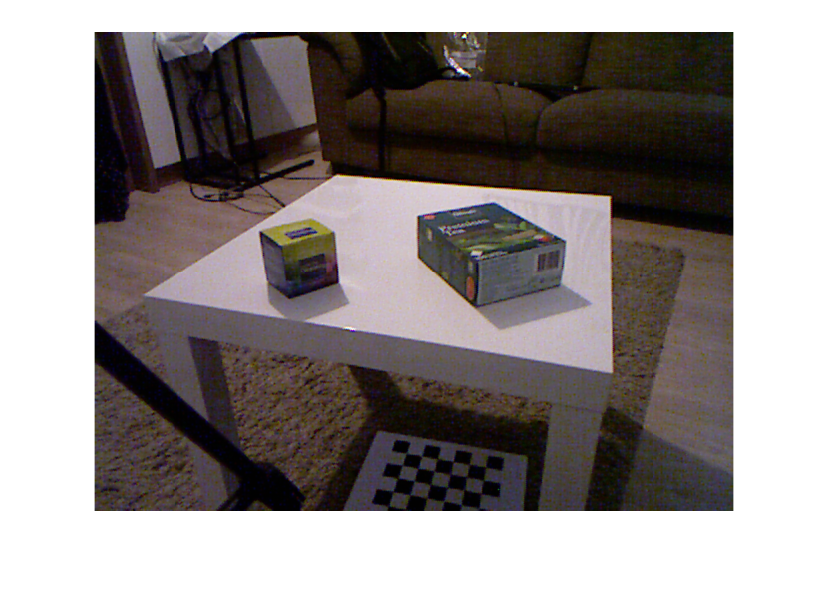

col = imread("herbata_kolor.png");
dep = imread("herbata_depth.png");

% Kinect
fx = 522.702;
fy = 522.091;
cx = 329.413;
cy = 253.105;

figure;
imshow(col);

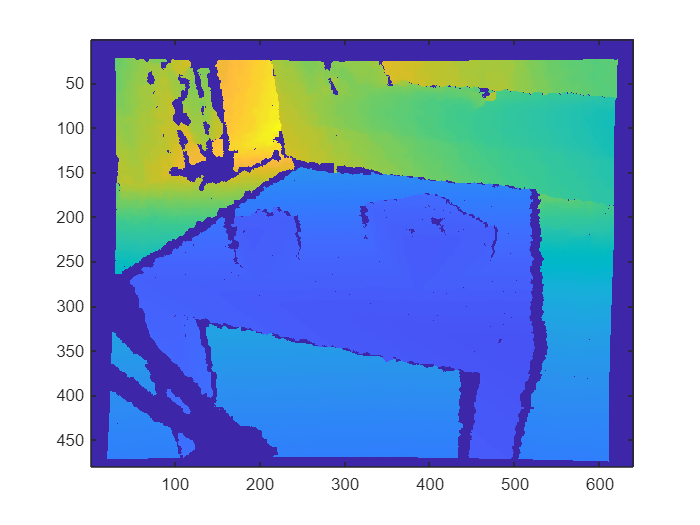

figure;
imagesc(dep);

### Przekształcenie głębi do chmury XYZ

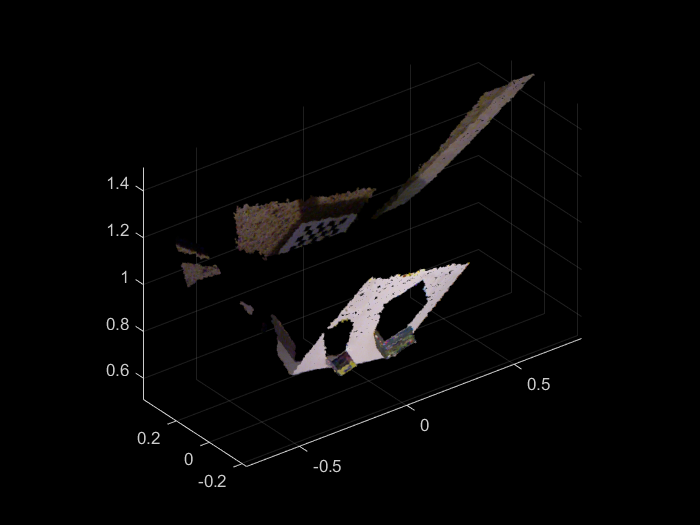

w = size(col, 2);
h = size(col, 1);

% współczynnik skali obrazu głębi (m/jedn)
ds = 0.001;
Z = double(dep) * ds;

% wycięcie punktów znajdujących się poza zakresem efektywnej pracy sensorów
Z(Z > 1.5) = NaN;
Z(Z < 0.1) = NaN;

% indeksy pikseli do równań reprojekcji głębi
u = repmat(1:w, [h, 1]);
v = repmat((1:h)', [1, w]);

% reprojekcja głębi
Y = (v - cy) / fy .* Z;
X = (u - cx) / fx .* Z;

XYZ = X;
XYZ(:,:,2) = Y;
XYZ(:,:,3) = Z;

% wynikowa chmura punktów
pc = pointCloud(XYZ, "Color", col);

pcshow(pc)

## Przekształcenie układu współrzędnych

### Dopasowanie modelu płaszczyzny do blatu stolika

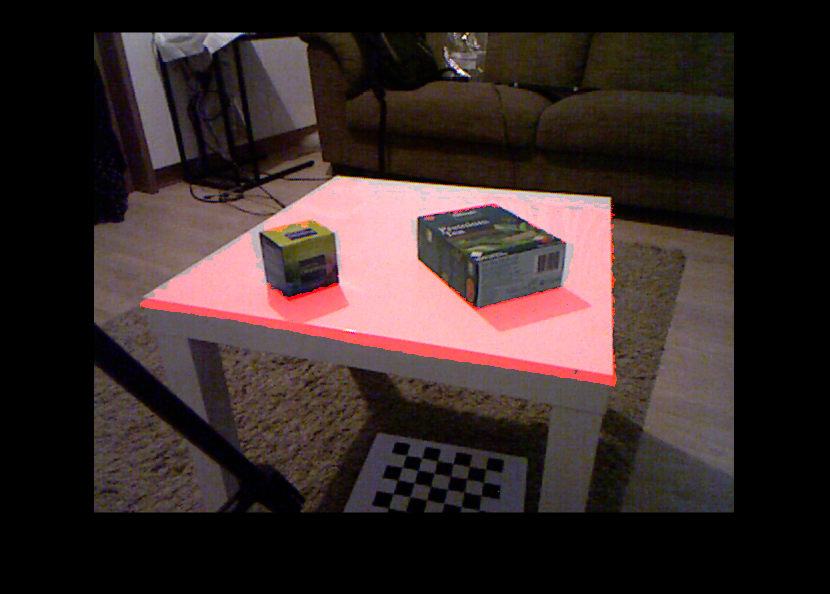

[plane, plane_ids, out_ids] = pcfitplane(pc, 0.01);

col_vis = col;
col_vis(plane_ids) = 255;
imshow(col_vis);

### Wyznaczenie macierzy transformacji świat-kamera

#### Orientacja powierzchni stolika

Nowy układ współrzędnych chcemy wyznaczyć w taki sposób, żeby oś *Z* wskazywała górę świata, oś *X* w prawą stronę kamery, a oś *Y *"jak wyjdzie" (do przodu).

Oś Z będzie wyrównana z wektorem normalnym do powierzchni stolika. Jeśli ten wektor jest skierowany w dół w obrazie z kamery (jego współrzędna Y jest dodatnia) to go odwracamy.

vk = plane.Normal;

if vk(2) > 0
    vk = -vk;
end
vk

vk =     0.0002   -0.8907   -0.4546


Wektor kierunkowy osi X pokazuje w prawo (w układzie kamery), natomiast wynikowy wektor osi Y powstaje przez przemnożenie wektorów X oraz Z.

vi = [1, 0, 0];
vj = cross(vk, vi);
vj = vj / norm(vj)

vj =          0   -0.4546    0.8907


Poprawka wektora osi x

vi = cross(vj, vk)

vi =     1.0000    0.0002    0.0001


Macierz obrotu jest prostym zestawieniem trzech wyznaczonych wektorów kierunkowych (z ich konstrukcji mamy pewność, że są względem siebie prostopadłe oraz znormalizowane.

R = [vi; vj; vk];
det(R)

ans = 1.0000

#### Położenie blatu stolika

Jako punkt bazowy nowego układu współrzędnych możemy przyjąć uśredniony punkt z powierzchni blatu

plane_points = select(pc, plane_ids);
t = mean(plane_points.Location)

t =    -0.0049   -0.0132    0.7040


Ostateczna macierz przekształcenia z układu stolika do układu kamery

T_oc = [R, [0;0;0]; t, 1]

T_oc =     1.0000    0.0002    0.0001         0
         0   -0.4546    0.8907         0
    0.0002   -0.8907   -0.4546         0
   -0.0049   -0.0132    0.7040    1.0000


### Przekształcenie z układu kamery do układu świata

Mając wyznaczone przekształcenie z układu świata do układu kamery, przekształćenie w drugą stronę powstaje przez odwrócenie macierz przekształcenia

T_co = inv(T_oc)

T_co =     1.0000         0    0.0002         0
    0.0002   -0.4546   -0.8907         0
    0.0001    0.8907   -0.4546         0
    0.0048   -0.6330    0.3083    1.0000


tr = rigid3d(T_co);

### Transformacja chmury punktów do układu stolika

Mając wyznaczone odpowiednie przekształcenie możemy przeliczyć współrzędne punktów tak, aby układ współrzędnych był wyrównany z blatem stolika

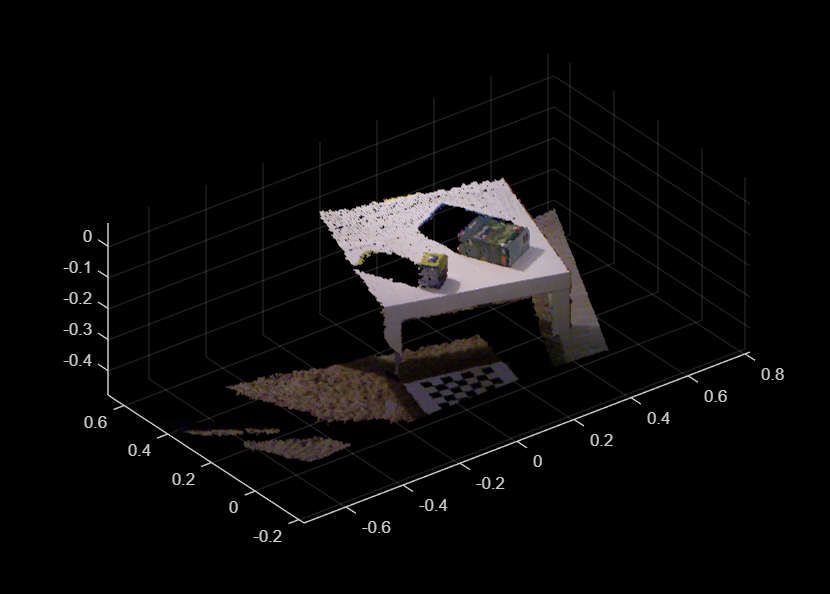

pc2 = pctransform(pc, tr);
pcshow(pc2);

Po przekształceniu chmura wciąż jest uporządkowana

size(pc2.Location)

ans =    480   640     3


## Analiza geometryczna obiektów na stoliku

### Wycięcie obszaru zainteresowania

Przekształcenie współrzędnych do układu związanego ze stolikiem pozwala na wygodne określanie obszaru zainteresowania. Do analizy obiektów leżących na stole możemy wybrać jedynie te punkty, które znajdują się wewnątrz bryły ograniczającej, tutaj o wymiarach *1 m x 1 m x 1 m:*

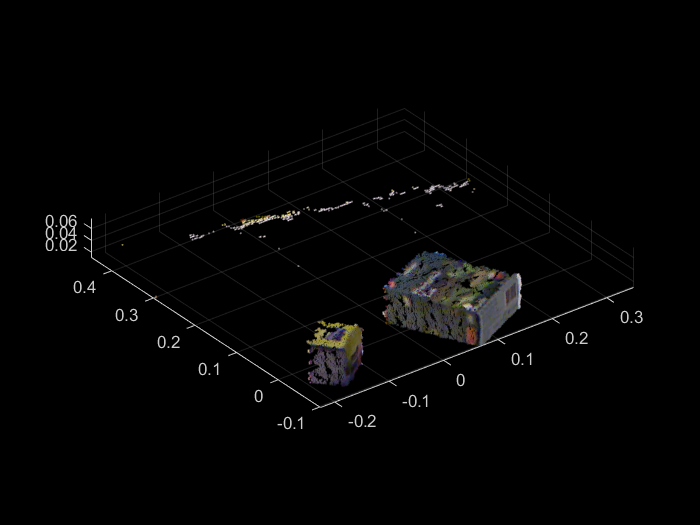

poi = findPointsInROI(pc2, [-0.5, 0.5, -0.5, 0.5, 0.01, 1 ]);

figure;
pcshow(select(pc2, poi));
hold on;

## Klasteryzacja chmury punktów

[labels,numClusters] = pcsegdist(select(pc2, poi), 0.05);
numClusters;

Wybór dwóch największych grup:

cl_s = zeros(4, 1);
for cl_id=1:numClusters
   cl_s(cl_id) = sum(labels==cl_id);
end
[~, best_cls] = maxk(cl_s, 2);

Dwie najliczniejsze grupy reprezentują pudełka leżące na stole:

cube1 = best_cls(1);
cube2 = best_cls(2);

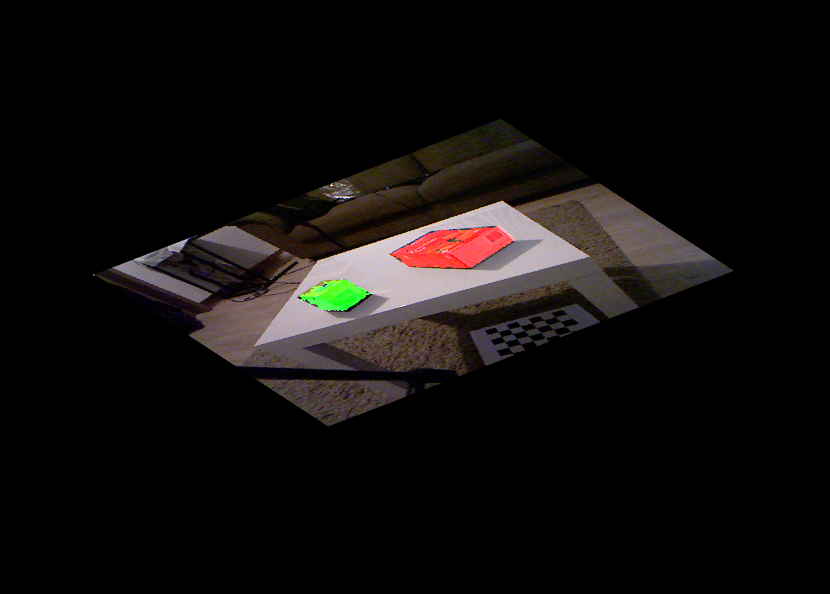

vis_group = col;
vis_group(poi(labels==cube1)) = 255;
vis_group(poi(labels==cube2) + w*h) = 255;
imshow(vis_group);

## **Dopasowanie modelu pierwszego pudełka:**

poi_cube1 = poi(labels==cube1);
herbata1 = pcfitcuboid(pc2, poi_cube1);

## **Dopasowanie modelu drugiego pudełka:**

poi_cube2 = poi(labels==cube2);
herbata2 = pcfitcuboid(pc2, poi_cube2);

## **Modele prostopadłościanów dopasowane do chmury punktów :**

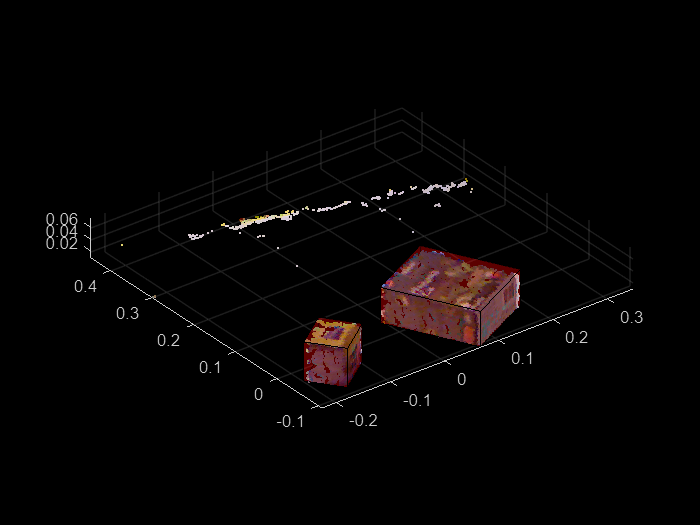

figure;
pcshow(select(pc2, poi));
hold on;
plot(herbata1);
hold on;
plot(herbata2)

## Środek masy, orientacja i wymiary pudełek:

herbata1

herbata1 =   cuboidModel with properties:

     Parameters: [0.0904 -0.0043 0.0401 0.1633 0.1369 0.0603 0 0 -63]
         Center: [0.0904 -0.0043 0.0401]
     Dimensions: [0.1633 0.1369 0.0603]
    Orientation: [0 0 -63]


**PUDEŁKO 1 **


$$\matrix{
\text{WYMIARY}    	& \text{rzeczywisty} 	& \text{dopasowany} & \text{różnica} \cr
\text{szerokość} &6.1cm &6.03cm &0.07cm \cr
\text{d\l ugość} &12.5cm &13.69cm &1.19cm \cr
\text{wysokość} &16.2cm &16.33cm &0.13cm \cr
}$$


herbata2 

herbata2 =   cuboidModel with properties:

     Parameters: [-0.1494 -0.0345 0.0432 0.0765 0.0670 0.0662 0 0 36.0000]
         Center: [-0.1494 -0.0345 0.0432]
     Dimensions: [0.0765 0.0670 0.0662]
    Orientation: [0 0 36.0000]


**PUDEŁKO 2 **


$$\matrix{
\text{WYMIARY}    	& \text{rzeczywisty} 	& \text{dopasowany} & \text{różnica} \cr
\text{szerokość} &7cm &7.65cm &0.65cm \cr
\text{d\l ugość} &7cm &6.7cm &0.3cm \cr
\text{wysokość} &6cm &6.62cm &0.62cm \cr
}$$
